# Práctica 1

## Entender el funcionamiento de diversos métodos numéricos

#### Método de punto fijo para encontrar raíces 

Supón que queremos encontrar la solución de la ecuación$f\left(x\right)=0$. Despejando de alguna manera, esta ecuación puede expresarse como $x=g\left(x\right)$. Ahora, se aplica el método iterativo de aproximaciones sucesivas dado por $x_{i+1} =g\left(x_i \right)$. Esto es, $x_1 =g\left(x_0 \right)$, $x_2 =g\left(x_1 \right)$ y así sucesivamente.Para que el método converja, la elección de $g\left(x\right)$ debe ser tal que $\left|g^{\prime } \left(x_0 \right)<1\right|$ donde $x_0$ es un valor inicial propuesto.

Usa este método para encontrar la solución de f(x) = cos x – 3x + 1 = 0

%Nota, esto es un newton o una bisección o algo así. 
f=@(x) cos(x) - 3*x + 1

f = function_handle with value:
    @(x)cos(x)-3*x+1


g=@(x)  (cos(x)+1)/3;
gprim=@(x) -sin(x)/3;

i=0;  max=100; 
condicion=true;
x0=-3; %x inicial
gprim(x0) %si es menor a 1

ans = 0.0470

while condicion
    x=x0;
    xn=g(x);
    condicion=i<max && f(x0)~=0 && abs((xn-x0)/xn)>eps ;
    i=i+1;
    x0=xn;
end
i

i = 25

%respuesta de la raiz
raiz=x0

raiz = 0.6071

f(raiz)

ans = 1.1102e-16

## Solucionar de forma numérica sistemas de ecuaciones lineales 

Resuelve de manera eficiente los dos siguientes sistemas de ecuaciones lineales $Ax_i =b_i ,i=1,2$:


$$\left\lbrack \begin{array}{cccccc}
1 & 1 & 0 & 1 & 0 & 0\\
0 & 1 & 1 & 0 & 1 & 0\\
0 & 0 & 1 & 1 & 0 & 1\\
1 & 0 & 0 & 1 & 1 & 0\\
1 & 1 & 0 & 0 & 1 & 1\\
0 & 1 & 1 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_{\textrm{i1}} \\
x_{\textrm{i2}} \\
x_{\textrm{i3}} \\
x_{\textrm{i4}} \\
x_{\textrm{i5}} \\
x_{\textrm{i6}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
b_{\textrm{i1}} \\
b_{\textrm{i2}} \\
b_{\textrm{i3}} \\
b_{\textrm{i4}} \\
b_{\textrm{i5}} \\
b_{\textrm{i6}} 
\end{array}\right\rbrack$$


A = gallery('dramadah', 6);

Encuentra la factorización LU de A:

[L,U,p,P]=Par2_LUps(A);

Usando forsub y backsub resuelve el primer sistema de ecuaciones (i=1)


$$b_1 =\left\lbrack \begin{array}{c}
0\\
1\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


b = [0;1;0;0;0;0];
x1=LUsubs(L,U,b(p))

x1 =     -2
     1
    -1
     1
     1
     0



%comprobacion
A*x1

ans =      0
     1
     0
     0
     0
     0


Usando forsub y backsub resuelve el segundo sistema de ecuaciones (i=2)


$$b_2 =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
1\\
0\\
0
\end{array}\right\rbrack$$


b2=[0;0;0;1;0;0];
x2=LUsubs(L,U,b2(p))

x2 =      4
    -2
     3
    -2
    -1
    -1



%comprobacion
A*x2

ans =      0
     0
     0
     1
     0
     0


## Solucionar de forma numérica sistemas de ecuaciones diferenciales

Resuelve el siguiente sistema de ecuaciones diferenciales de primer orden.


$$\frac{\mathrm{d}}{\mathrm{d}t}x=-y$$
          
$$x\left(0\right)=r$$



$$\frac{\mathrm{d}}{\mathrm{d}t}y=x$$
            
$$y\left(0\right)=0$$


Grafica $x\;\textrm{vs}\ldotp y$ para $t\in \left\lbrack 0,20\right\rbrack$.

Usa el método de Euler con h =0.01.

%y=[x,y]
y0=[1,0];
t0=0;
tf=20;
h=0.01;

f=@(t,y) [-y(2) ; y(1)]

f = function_handle with value:
    @(t,y)[-y(2);y(1)]


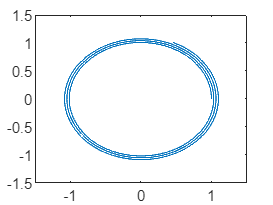

[t,y]= TerPar_odeEuler(f,t0,y0,h, tf);
plot(y(1,:),y(2,:));axis([-1.5 1.5 -1.5 1.5])

Usa el método de Euler con h =0.0001.

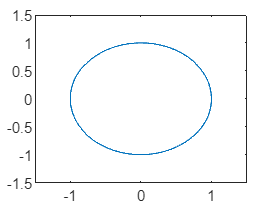

[t2,y2]= TerPar_odeEuler(f,t0,y0,0.0001,tf);%TerPar_odeEuler(f, to, yo, h, tf)
plot(y2(1,:),y2(2,:));axis([-1.5 1.5 -1.5 1.5])

¿Qué puedes concluir de los resultados?

%que con el metodo odeEuler, mientras la h sea mas pequeña tendra más
%precision, por lo que se ecomendaría ocuparlo con  h chiquitas

## **METODOS/FUNCIONES**

LUSUBS

function x=LUsubs(L,U,b)
    %tiene que recibir en b
    %P*b   b(p)
    [m,n] = size(b);
    %FORSUB
        y=zeros(size(b));
       y(1,:)=b(1,:);
        for i=2:1: m
            y(i,:)= b(i,:)- L(i,1:i-1) * y(1:i-1,:);
        end
    %BACKSUB
    
    x = zeros(size(b));
    x(m,:)=y(m,:)/U(m,m);
    for i = m-1 : -1 : 1
        x(i,:)=(y(i,:)- U(i, i+1:end)*x(i+1:end,:) ) / U(i,i);
    end
end